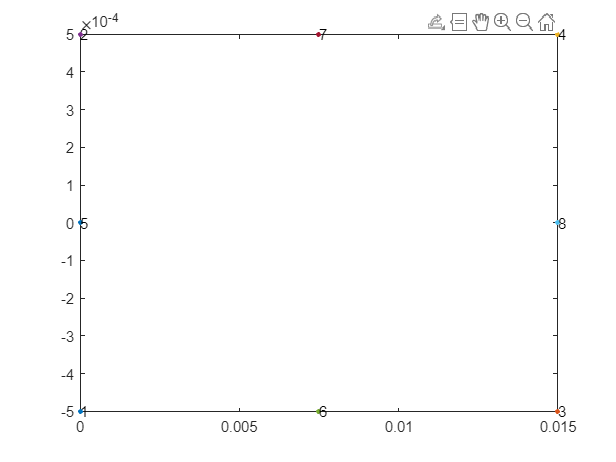

位置 1 处的索引超出数组边界。索引不能超过 1。

出错 draw_mesh>draw (第 19 行)
ele1 = Ielement(num,:);

addpath('.\import')

% [Nnode, Nelement, Coordinate, Ielement] = read_mesh_info("mesh_simple.dat");

num = 1:Nnode; % 绘制的单元编号
% num = 1:2; % 绘制的单元编号
t = 0.02; % 动画时间

for i = 1:length(num)
	draw(num(i),t,Ielement,Coordinate)
end


axis padded
axis([0 15e-3 -.5e-3 .5e-3])
hold off


function draw(num,t,Ielement,Coordinate)
% global Ielement Coordinate
ele1 = Ielement(num,:);
for i = 1:length(ele1)
	plot(Coordinate(ele1(i),1),Coordinate(ele1(i),2),'.','MarkerSize',10)
	xlim([min(Coordinate(ele1(:),1)),max(Coordinate(ele1(:),1))])
	ylim([min(Coordinate(ele1(:),2)),max(Coordinate(ele1(:),2))])
	
	text(Coordinate(ele1(i),1),Coordinate(ele1(i),2),num2str(ele1(i)))
	hold on
% 	pause(t)
end
end
